This is a livescript for the adaptive MC method in Task 1, after the Richardson stuff.

clc
clear


randomfield = 1;
I = 128;
M = 1*10^4;
N = 10;
nu = 'infinity';
sigma = 0.5;
counter = 1;
TOL = 0.1;
runn_err = 2*TOL;

while runn_err>TOL
    
    x = linspace(0, 1, I+1);
    h = 1/I;
    x_half = zeros([I+1 1]);
    for k=1:I
        x_half(k) = (x(k+1) + x(k))/2;
    end
    %{
    if randomfield == 2
        C = Matern_specialcases_only(x_half, nu);
        [EVec, EVal] = eig(C);
        SV = zeros([i 1]);
        EVec = flip(EVec, 2);
        for k=1:i
            SV(k) = sqrt(EVal(i+1-k, i+1-k));
        end
    end
    %}
    rng(1)
    x_hat = linspace(0, 1, N + 1);
    Y = normrnd(0, 1, [N M]);
    a = zeros([M I+1]);
    
    for sample=1:M
        if randomfield == 1
            ind = zeros([length(x) N]);
        
            % Calculate for every node in the I mesh
            for l=1:length(x)
                % Check for every node in I mesh if its in [x^(k-1), x^(k)]
                for r=2:N+1
                    if (x(l) >= x_hat(r-1) & x(l) <= x_hat(r))
                        ind(l, r-1) = Y(r-1, sample);
                    else
                        ind(l, r-1) = 0;
                    end
                end
            end
            
            stairs = crop(ind);
            a(sample, :) = 1 + 0.5*stairs;
        end
        if randomfield == 2
            inner = zeros([length(x) N]);
            for k=1:N
                inner(:, k) = SV(k)*Y(k).*EVec(:, k);
            end
            kappa = sum(inner, 2);
            a(sample, :) = exp(kappa);
        end
    end
    
    F = zeros([I+1 1]);
    for j=1:I+1
        F(j) = 4*pi^2*cos(2*pi*x_half(j));
    end
    
    u_h = zeros([M I+1]);
    
    for sample=1:M
        A = zeros([I+1 I+1]);
        for j=2:I
           A(j, j-1) = -a(sample, j-1)/(h^2);
           A(j, j) = (a(sample, j-1) + a(sample, j+1))/(h^2);
           A(j, j+1) = -a(sample, j+1)/(h^2);
        end
        
        u_h(sample, :) = A(2:I, :)\F(2:I);
    end

    QuantOfInt = zeros([M 1]);
    QuantOfInt2 = zeros([M 1]);
    for sample=1:M
        QuantOfInt(sample) = h*sum(u_h(sample, :));
        QuantOfInt2(sample) = 2*h*sum(u_h(sample, 1:2:end));
        MC_est(sample) = 1/sample*sum(QuantOfInt2(1:sample));
        if sample>1
            MC_var(sample) = 1/(sample-1)*sum((QuantOfInt2(1:sample) - MC_est(sample)).^2);
            abs_err(sample) = abs(1/sample*sum(QuantOfInt - QuantOfInt2));
        rel_err(sample) = abs_err(sample)/abs(MC_est(sample));
        stat_err(sample) = 1.96*sqrt(MC_var(sample))/(sqrt(sample)*abs(MC_est(sample)));
        end
    end
    MC_var(end)
    final_stat_err = stat_err(end)
    final_rel_err = rel_err(end)
    runn_err = final_rel_err + final_stat_err
    runn_err = 0.01
    if (final_stat_err > 0.05)
        M = M + 200;
    else
        I = I + 10;
    end
    counter = counter + 1
end

ans = 7.7267e+04

final_stat_err = 0.6058

final_rel_err = 4.6698e-05

runn_err = 0.6059

runn_err = 0.0100

counter = 2

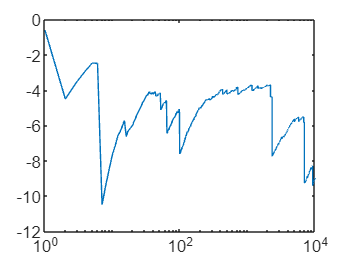


semilogx(1:M-200, MC_est)